step = 0.1;
endtime = 30; % start time is zero no need to define
T = 0:step:endtime;
StepFunc = zeros(size(T))

StepFunc =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


StepFunc(:,50:end) = 1

StepFunc =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1


Reference = StepFunc

Reference =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1



% simlution function in form of A*u^2+B*u+C
Y = 1./(StepFunc .* StepFunc + StepFunc*5+6)

Y =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.0833


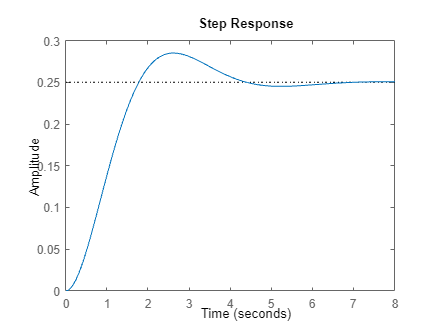

num = 1;
den = [2,3,4];
G = tf(num,den);
stepplot(G)

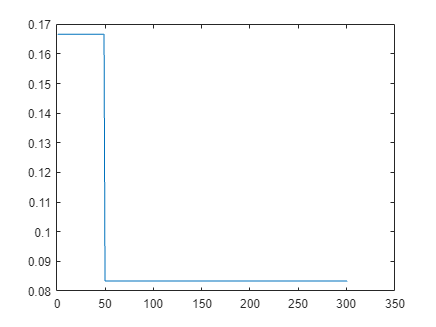


clf
plot(Y)


Kp = 0.3;
Kd = 0.02;
Ki = 0.2;